splitfolder = 'split1'

per =      0     5    10    15    20    25


optrank_growth = 2

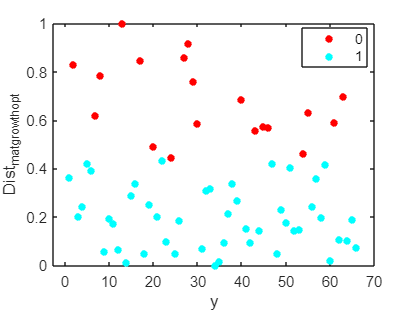

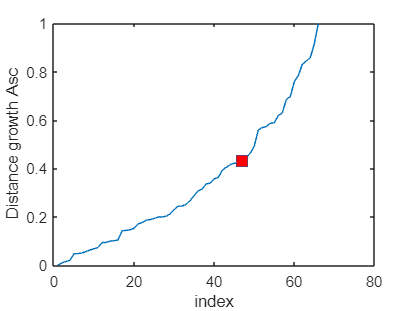

optrank_nongrowth = 1

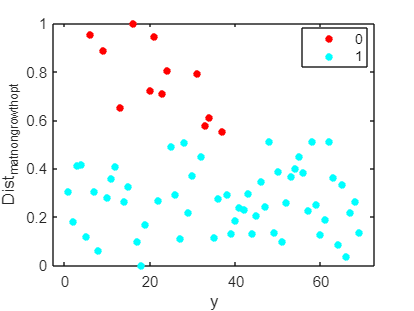

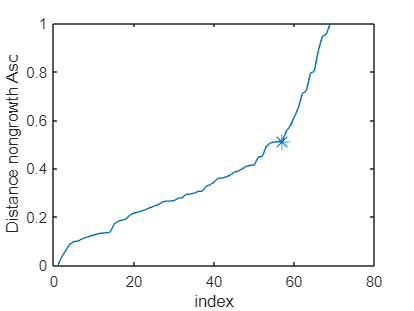

optrank_growth = 3

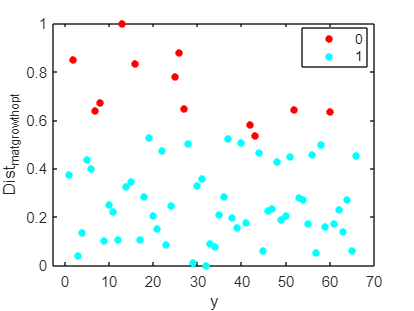

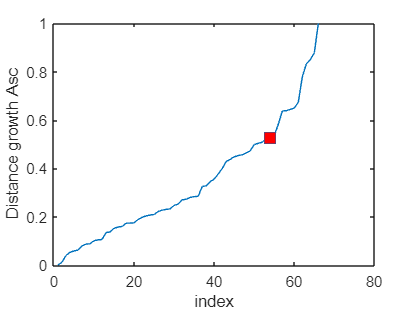

optrank_nongrowth = 1

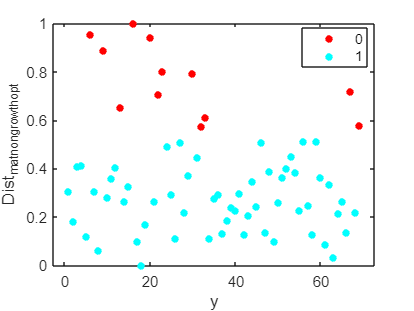

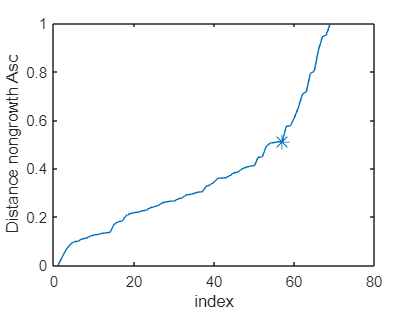

optrank_growth = 3

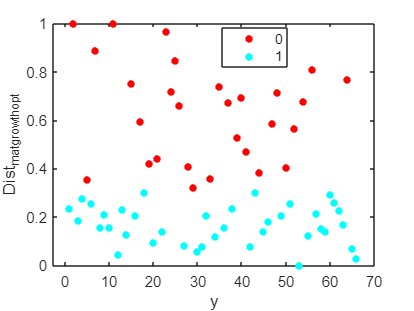

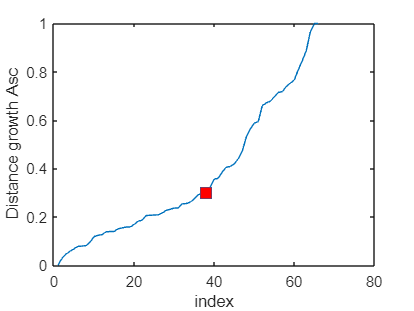

optrank_nongrowth = 1

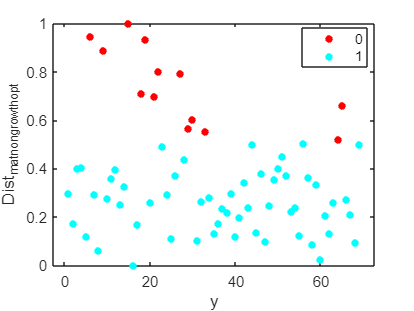

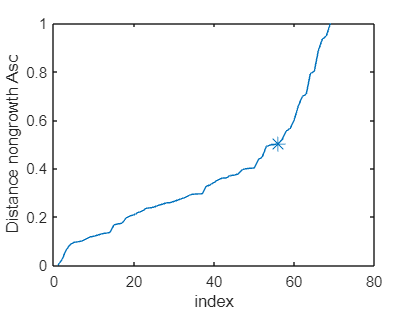

optrank_growth = 3

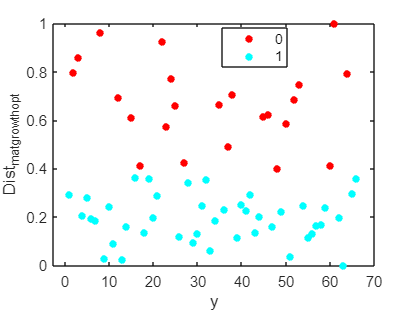

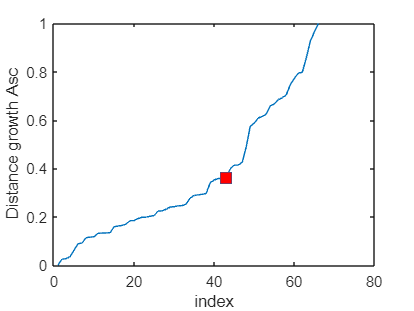

optrank_nongrowth = 3

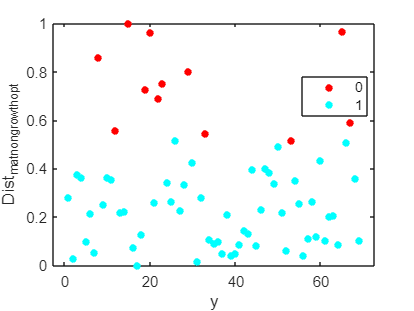

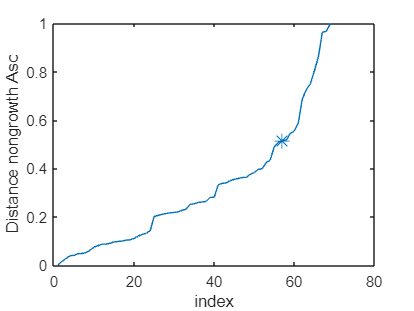

optrank_growth = 3

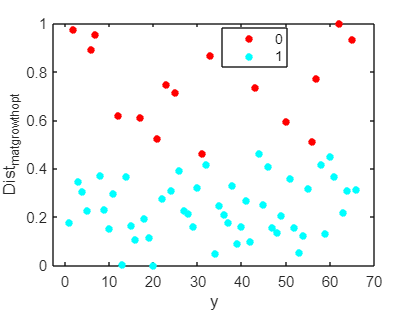

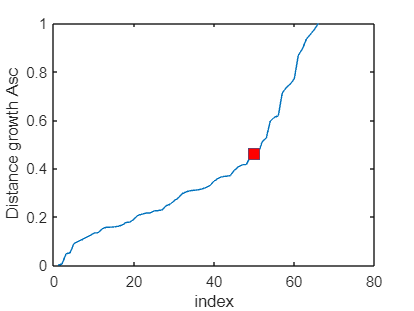

optrank_nongrowth = 1

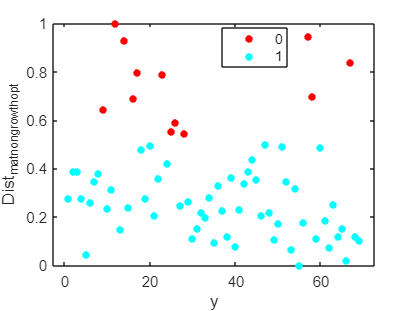

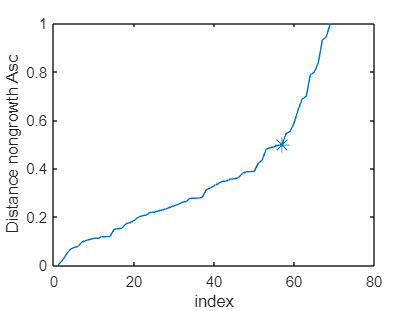

optrank_growth = 2

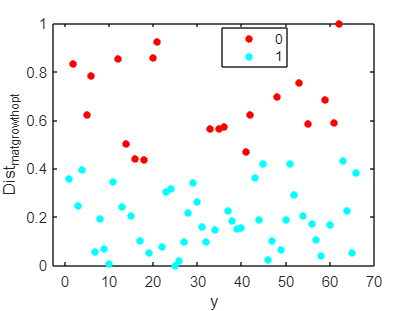

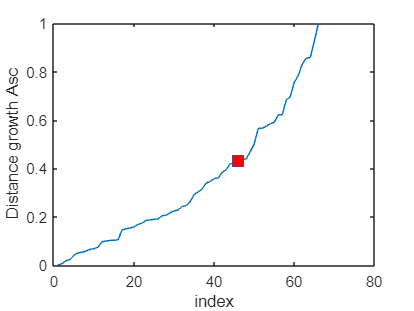

optrank_nongrowth = 1

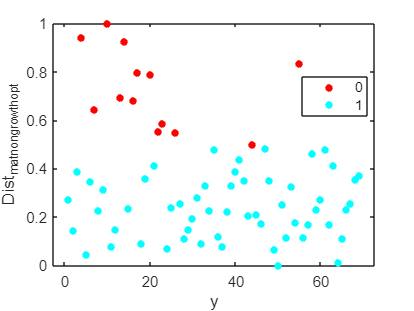

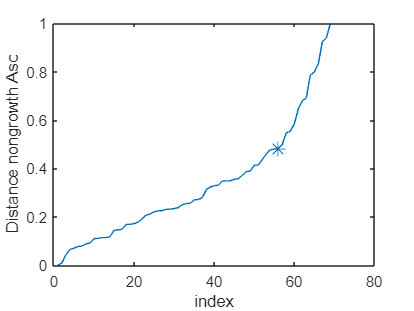

splitfolder = 'split2'

per =      0     5    10    15    20    25


optrank_growth = 1

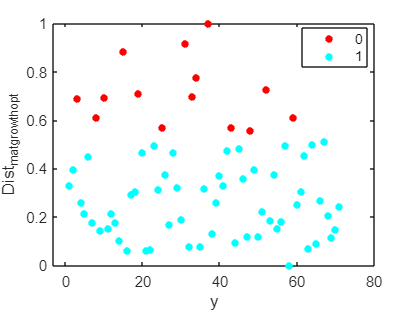

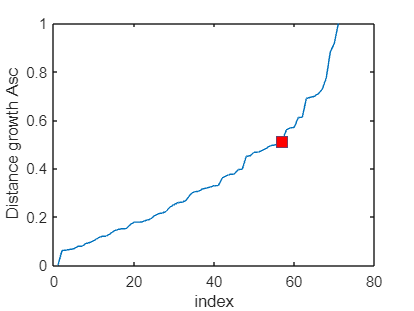

optrank_nongrowth = 2

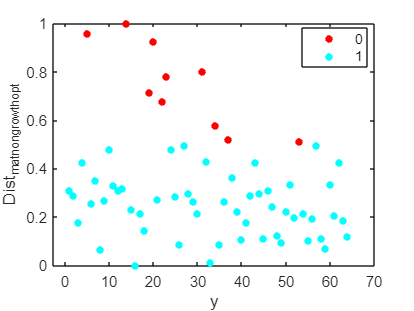

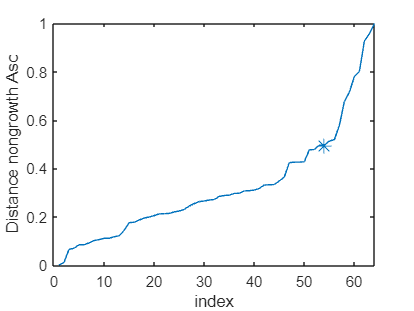

optrank_growth = 1

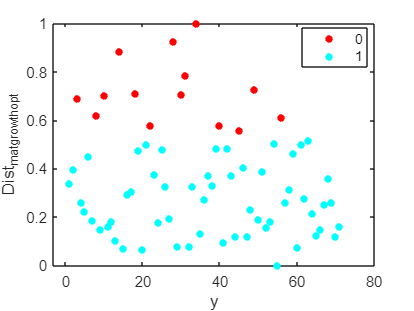

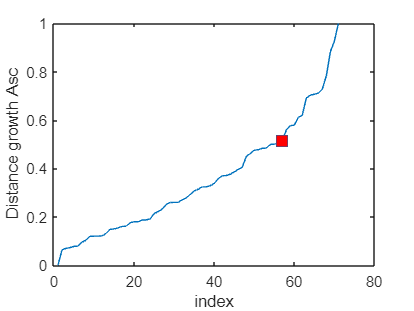

optrank_nongrowth = 2

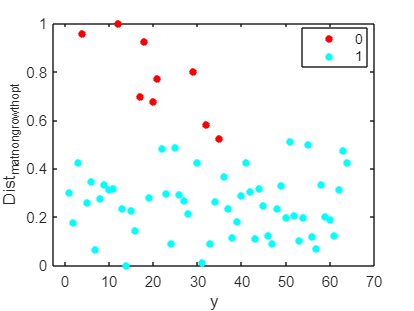

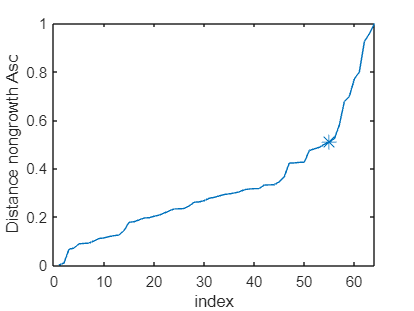

optrank_growth = 1

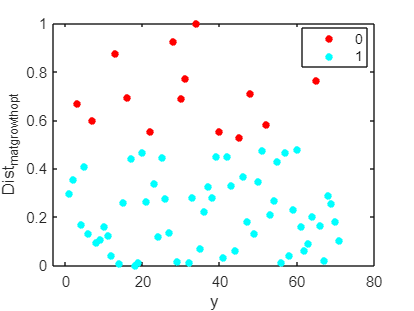

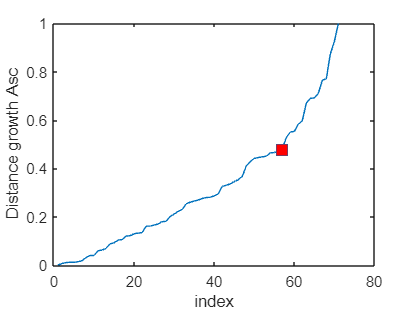

optrank_nongrowth = 2

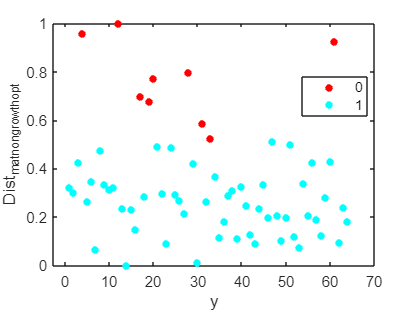

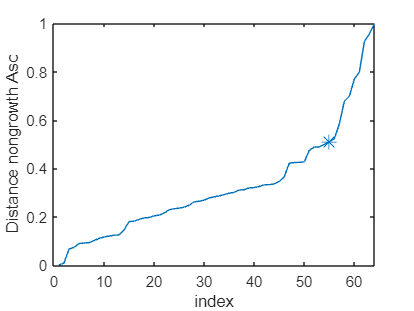

optrank_growth = 1

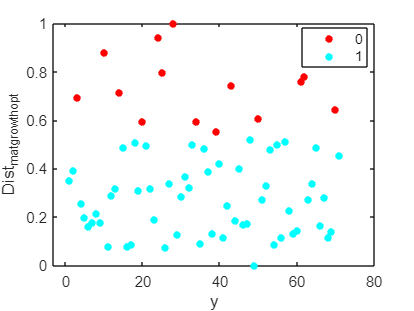

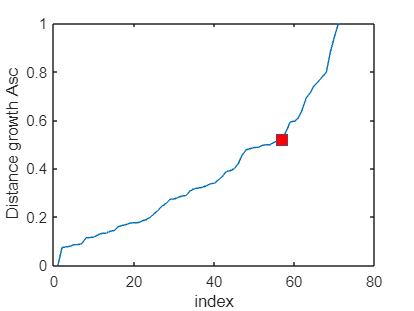

optrank_nongrowth = 2

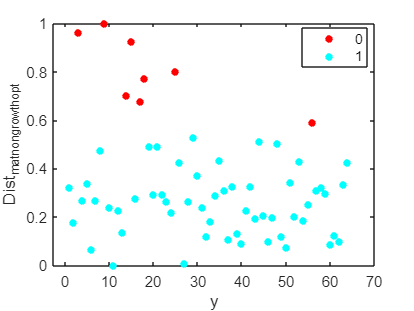

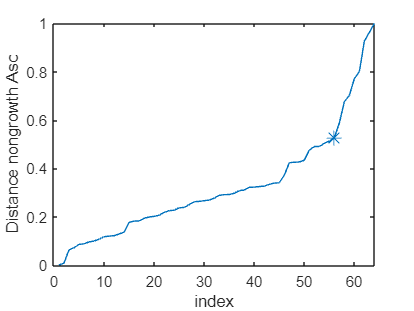

optrank_growth = 1

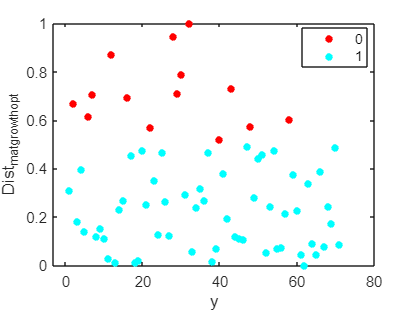

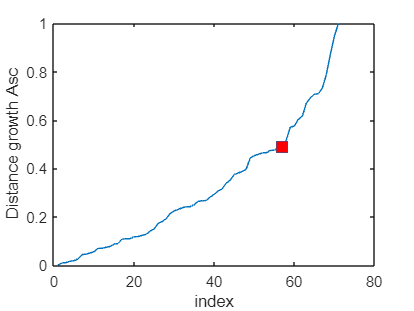

optrank_nongrowth = 2

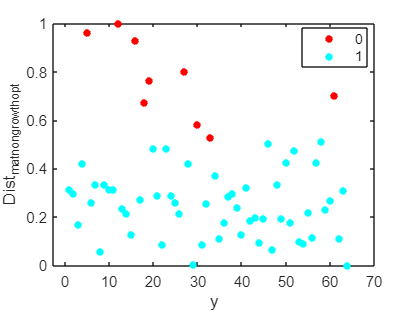

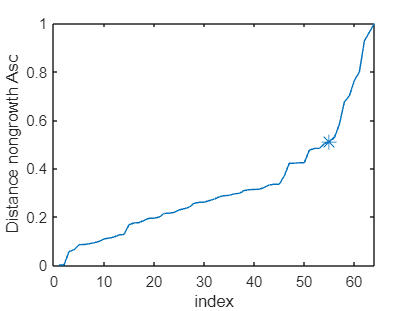

optrank_growth = 1

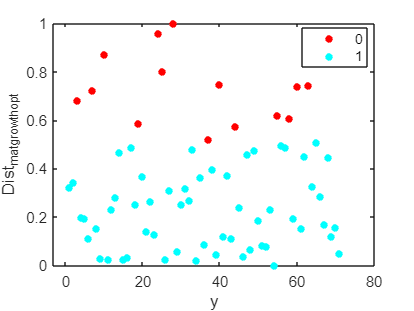

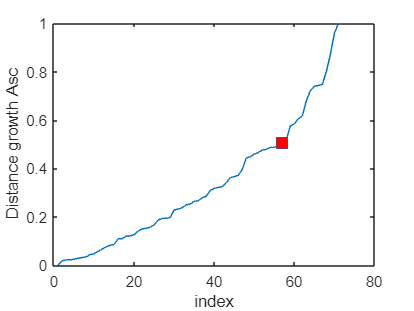

optrank_nongrowth = 2

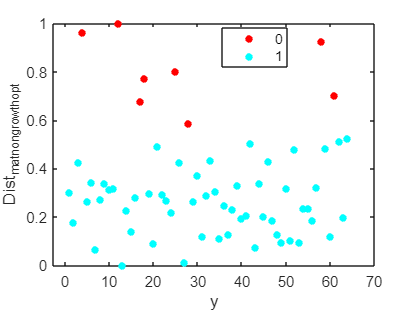

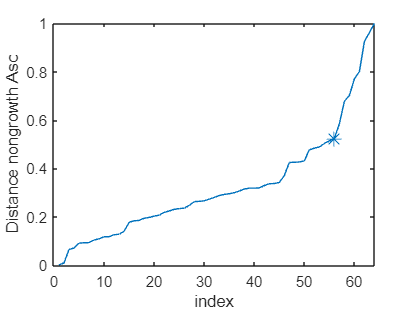

splitfolder = 'split3'

per =      0     5    10    15    20    25


optrank_growth = 3

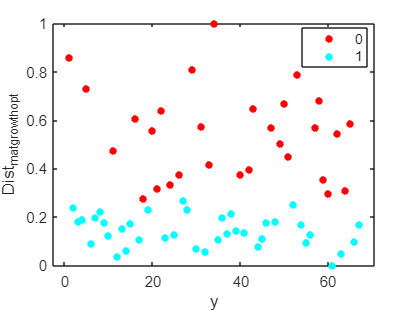

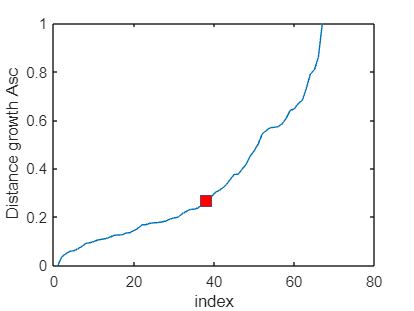

optrank_nongrowth = 1

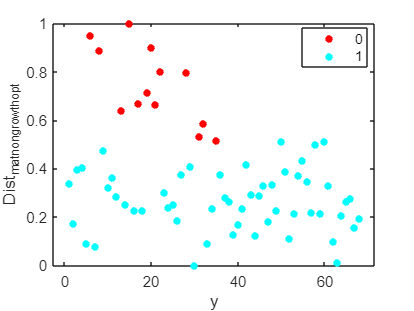

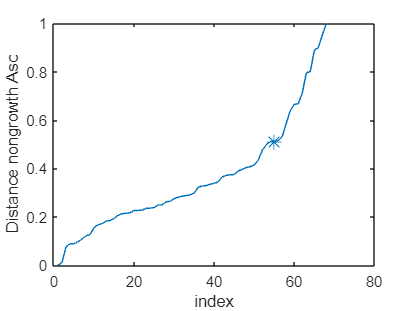

optrank_growth = 3

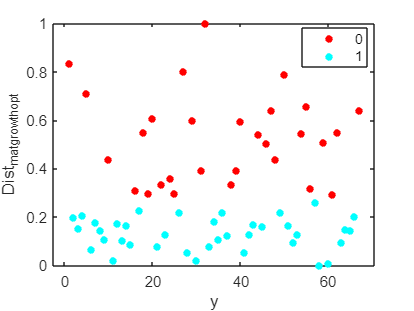

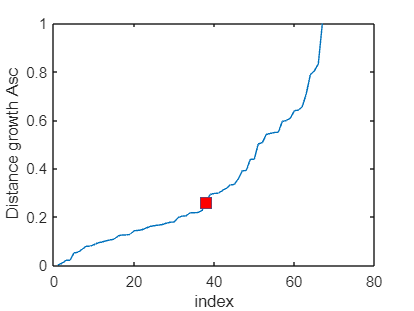

optrank_nongrowth = 2

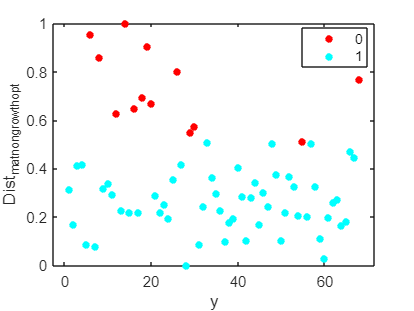

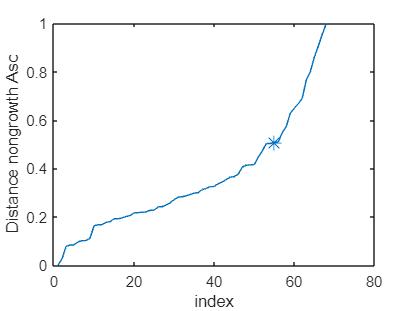

optrank_growth = 3

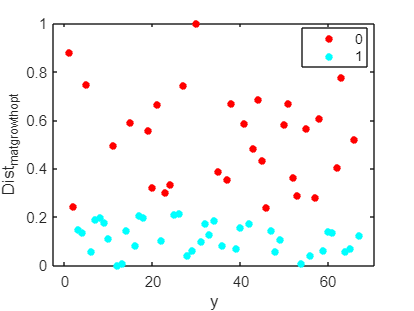

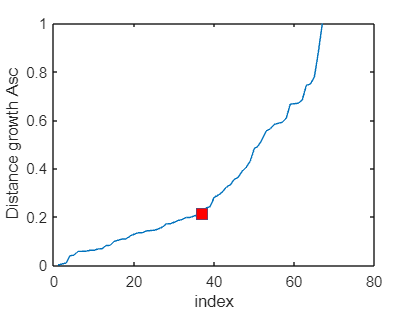

optrank_nongrowth = 2

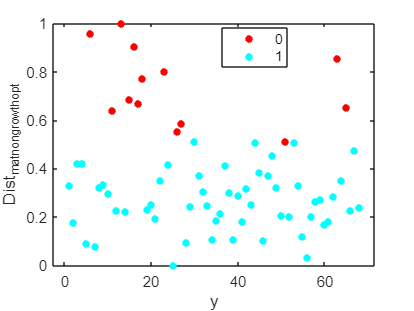

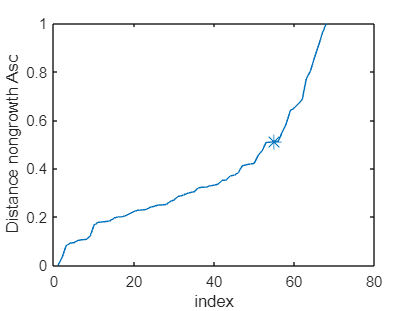

optrank_growth = 3

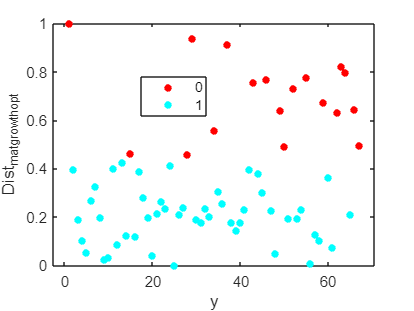

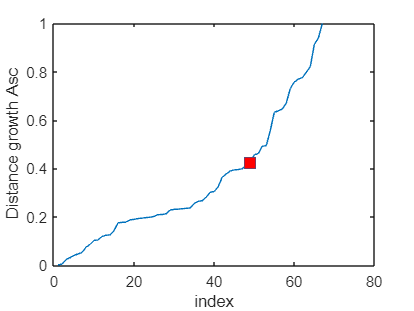

optrank_nongrowth = 1

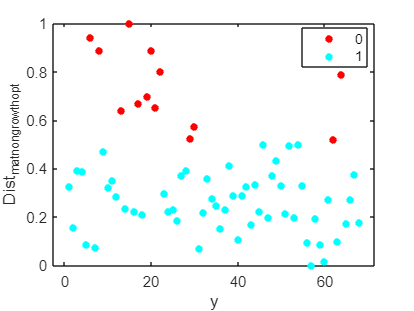

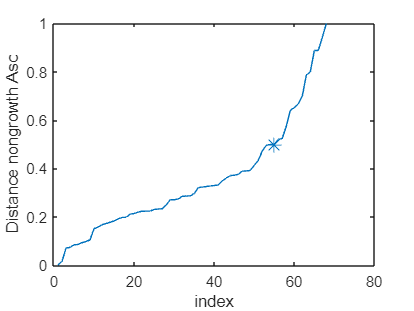

optrank_growth = 3

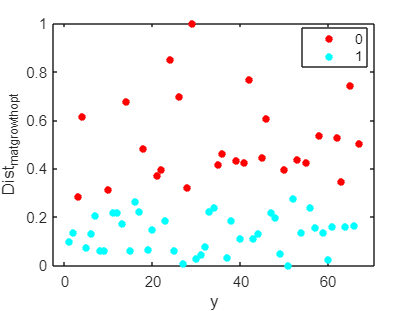

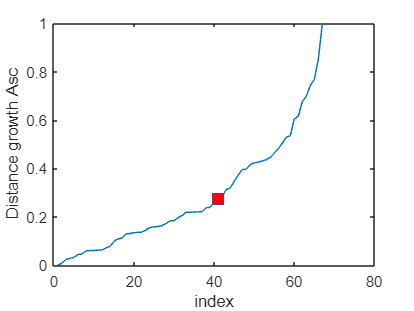

optrank_nongrowth = 3

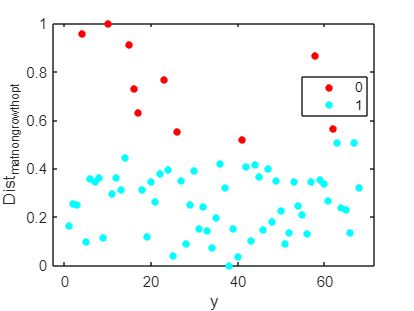

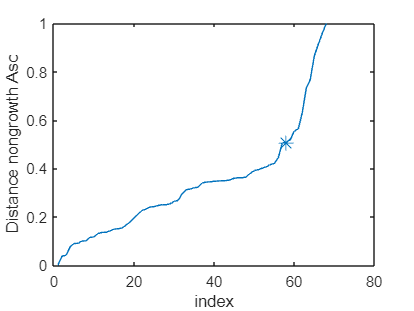

optrank_growth = 3

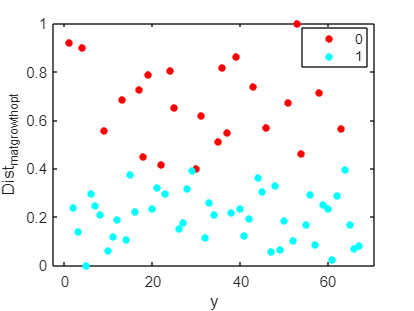

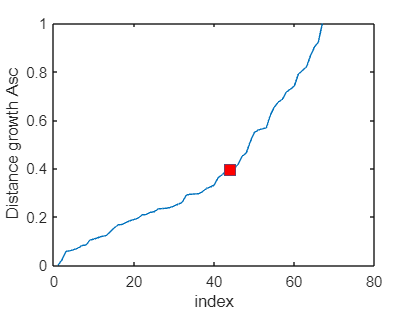

optrank_nongrowth = 2

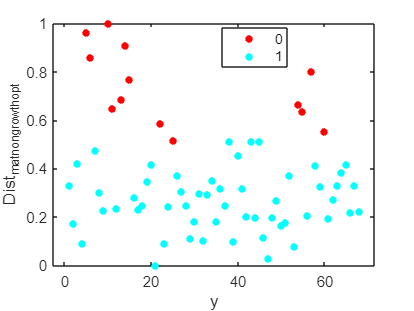

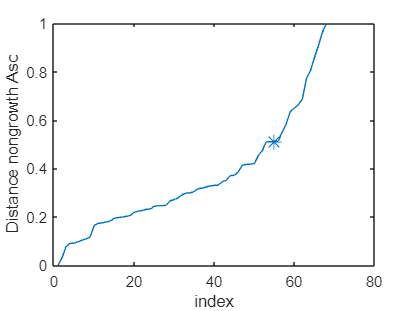

splitfolder = 'split4'

per =      0     5    10    15    20    25


optrank_growth = 2

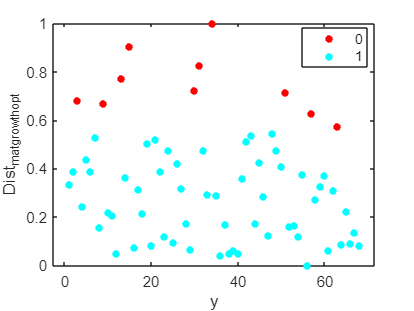

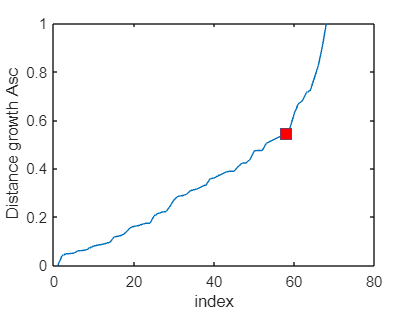

optrank_nongrowth = 1

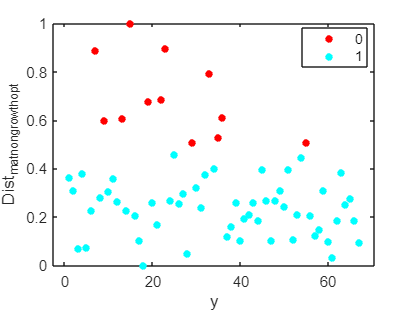

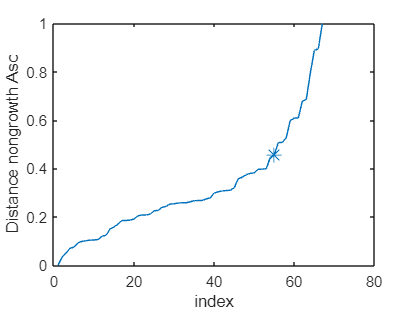

optrank_growth = 1

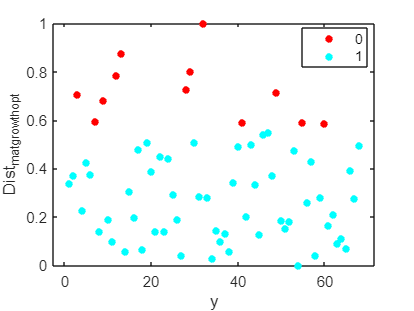

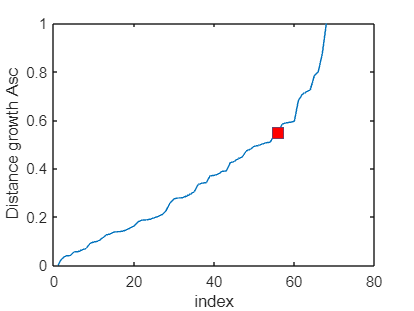

optrank_nongrowth = 1

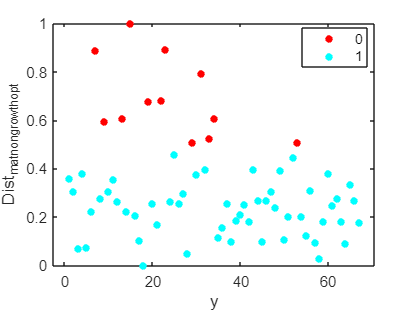

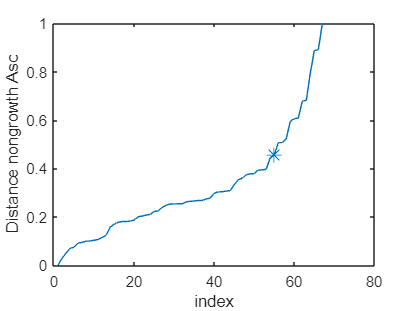

optrank_growth = 1

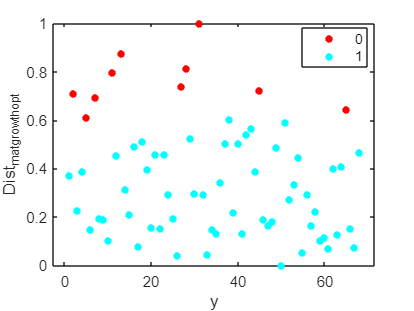

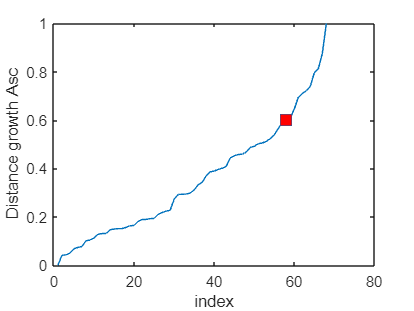

optrank_nongrowth = 1

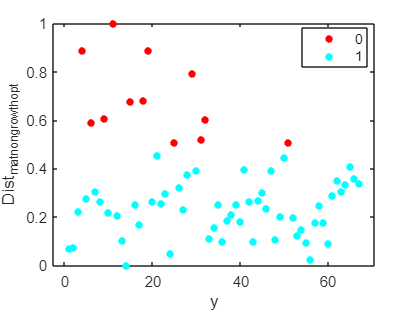

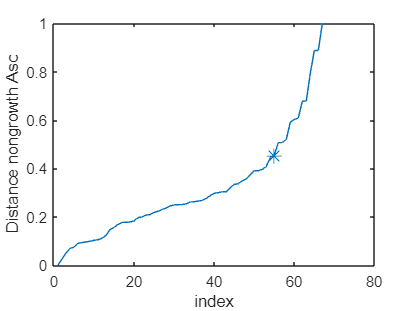

optrank_growth = 1

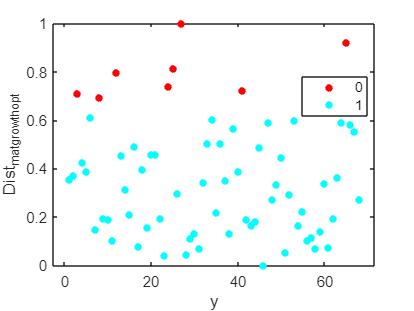

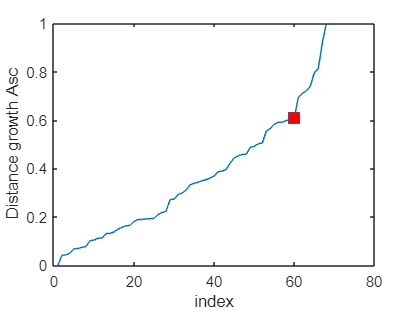

optrank_nongrowth = 1

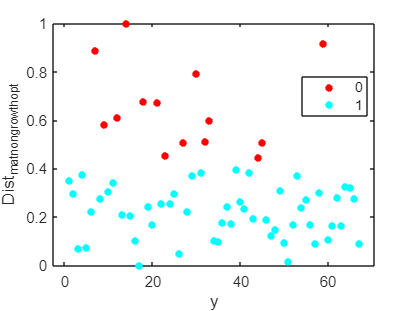

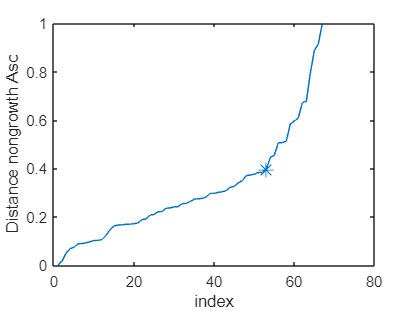

optrank_growth = 2

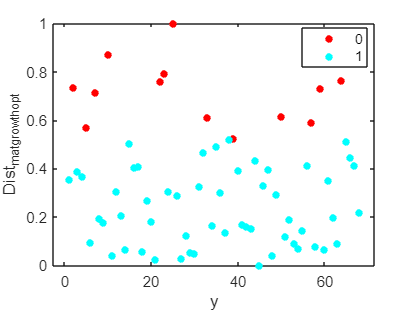

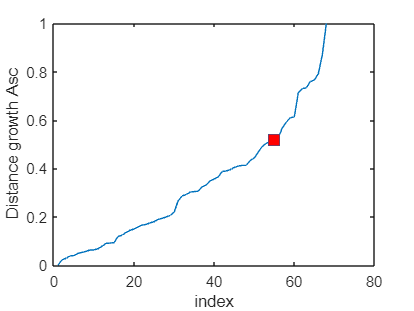

optrank_nongrowth = 2

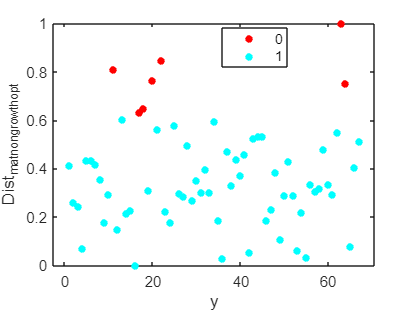

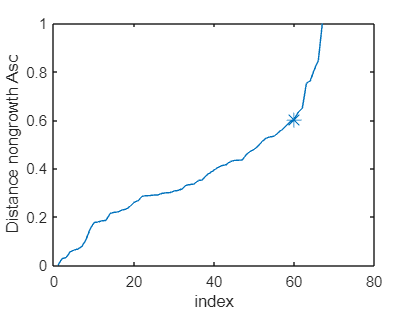

optrank_growth = 3

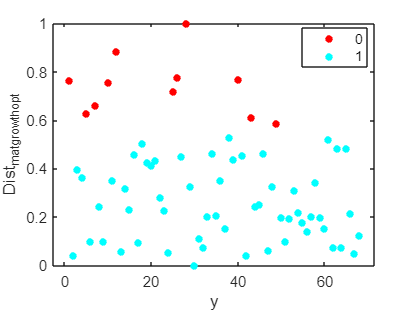

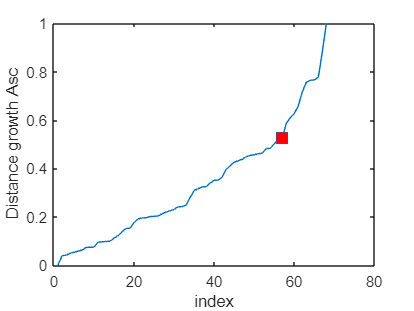

optrank_nongrowth = 2

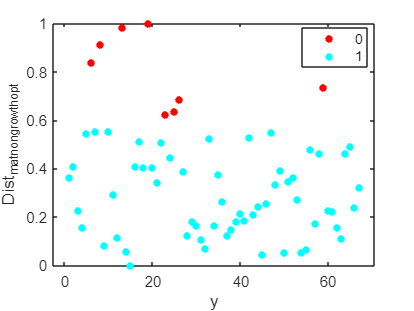

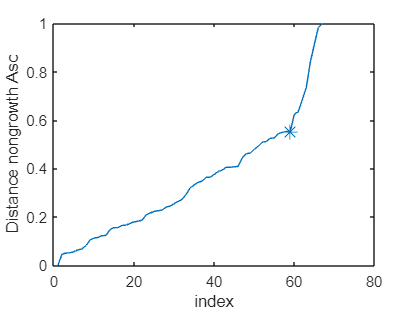

splitfolder = 'split5'

per =      0     5    10    15    20    25


optrank_growth = 3

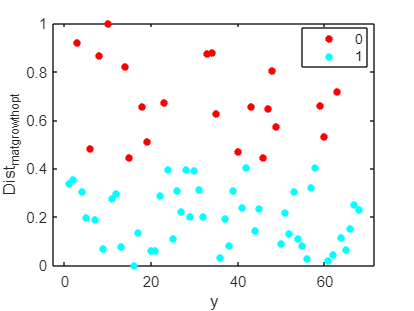

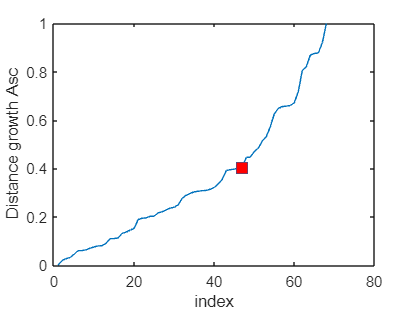

optrank_nongrowth = 3

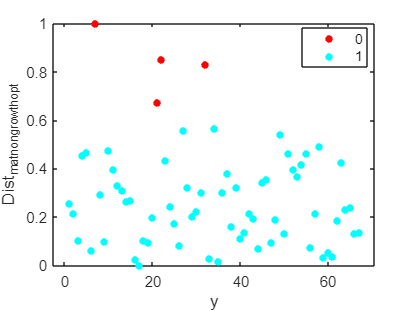

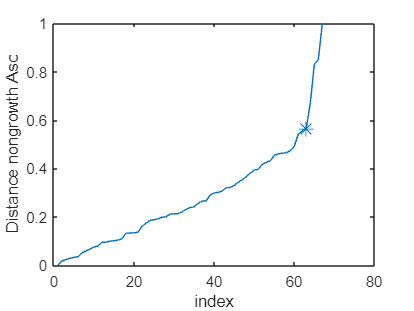

optrank_growth = 3

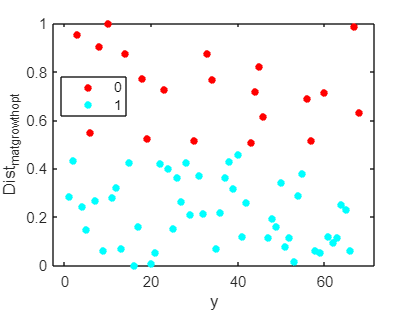

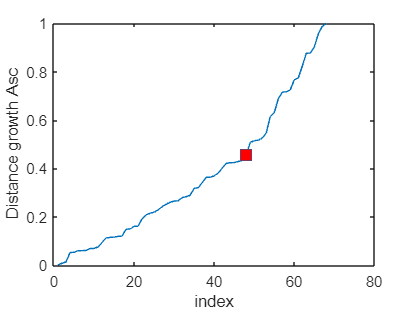

optrank_nongrowth = 2

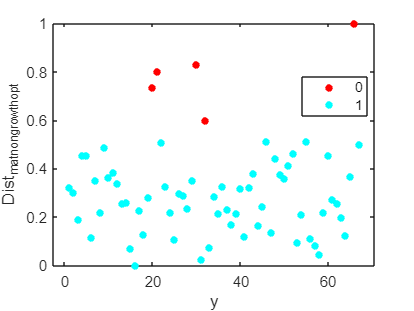

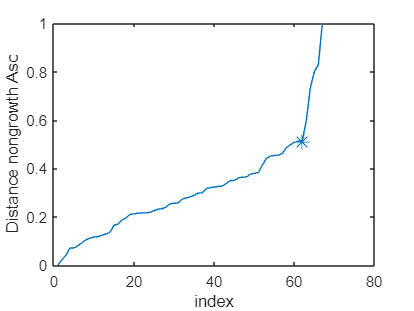

optrank_growth = 3

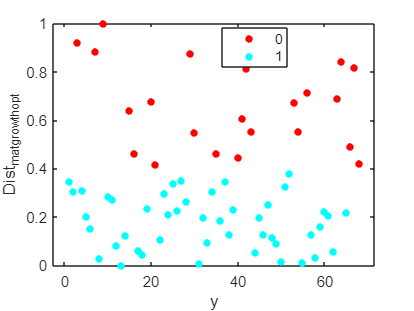

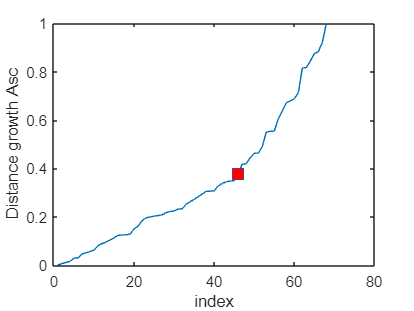

optrank_nongrowth = 2

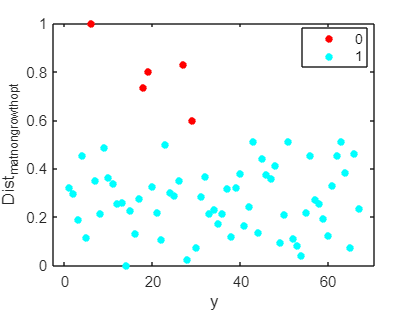

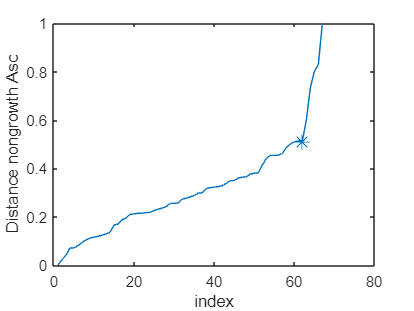

optrank_growth = 3

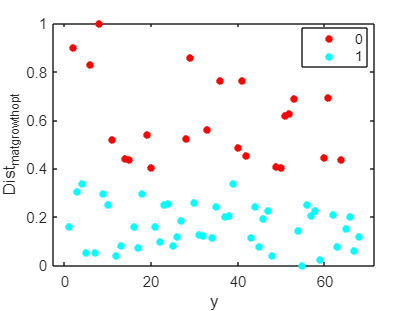

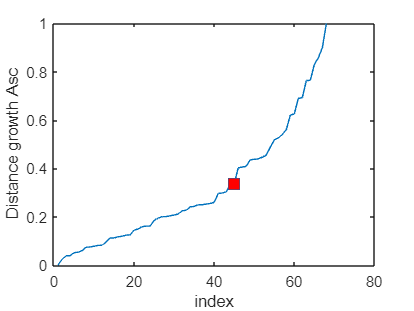

optrank_nongrowth = 3

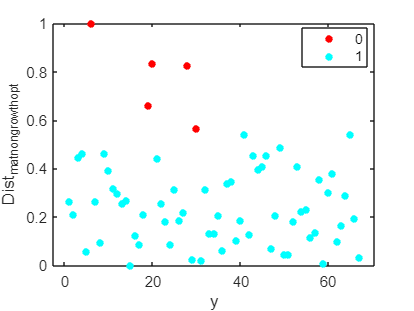

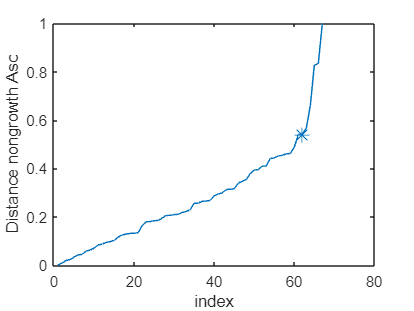

optrank_growth = 3

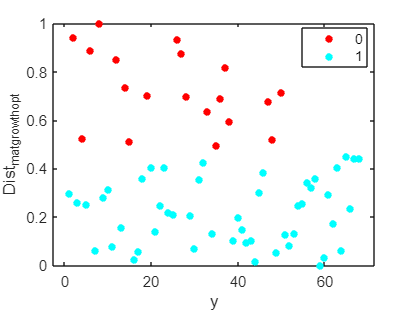

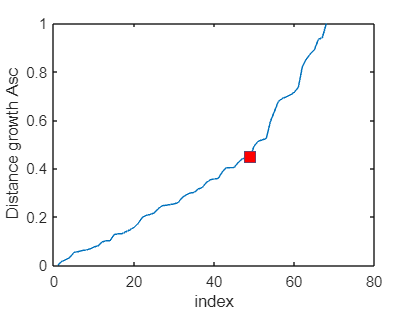

optrank_nongrowth = 2

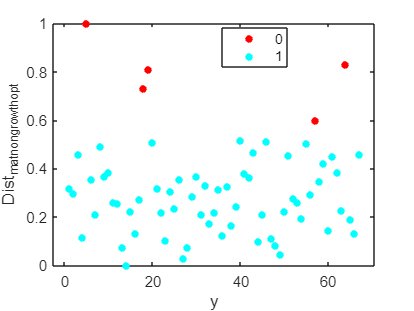

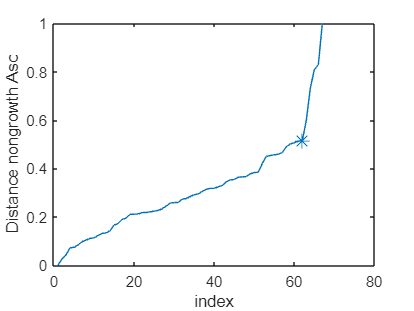

optrank_growth = 3

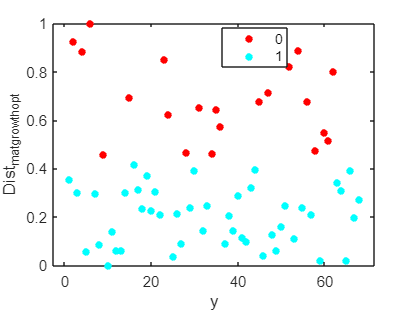

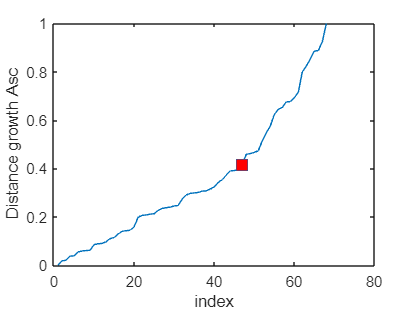

optrank_nongrowth = 2

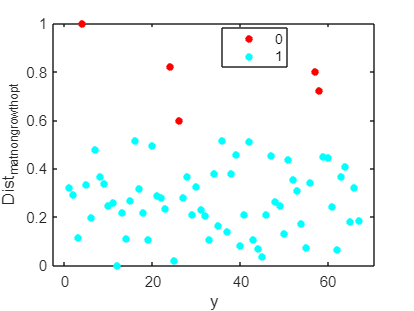

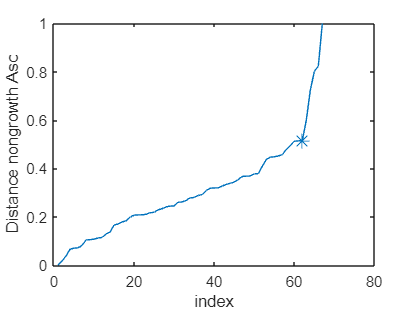

splitfolder = 'split6'

per =      0     5    10    15    20    25


optrank_growth = 3

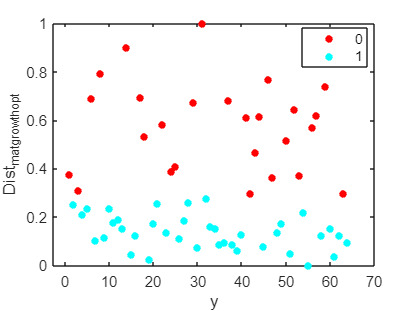

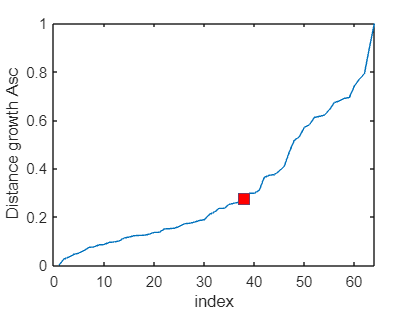

optrank_nongrowth = 1

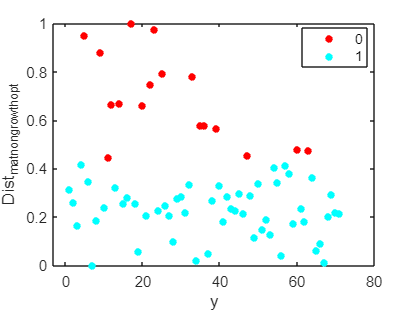

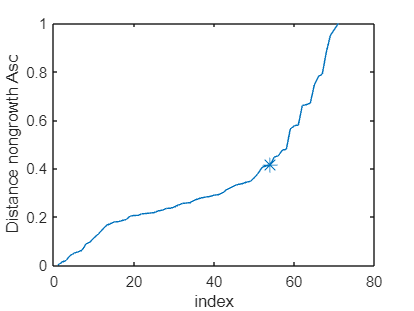

optrank_growth = 3

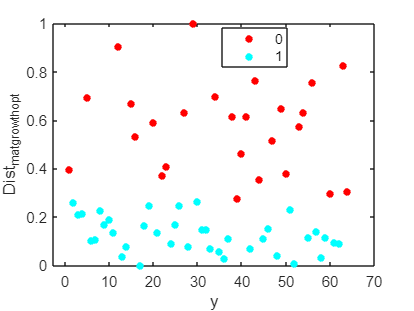

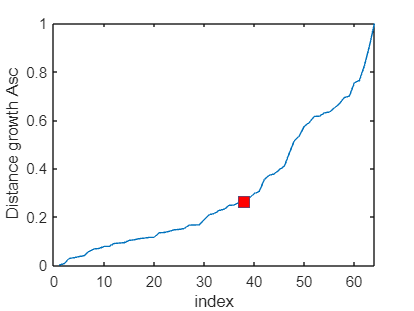

optrank_nongrowth = 1

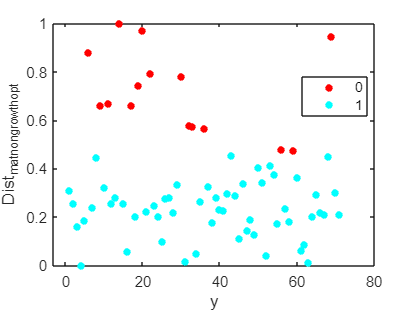

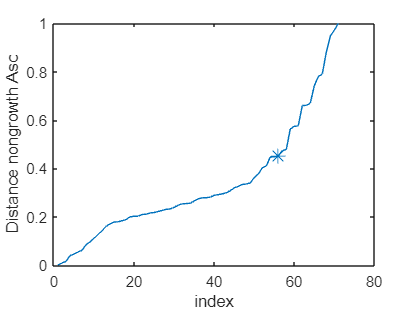

optrank_growth = 3

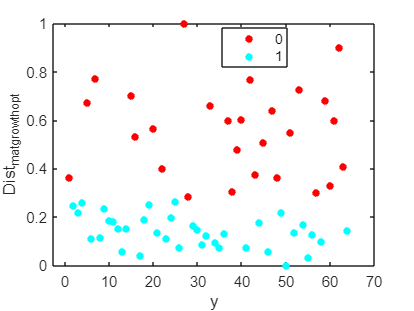

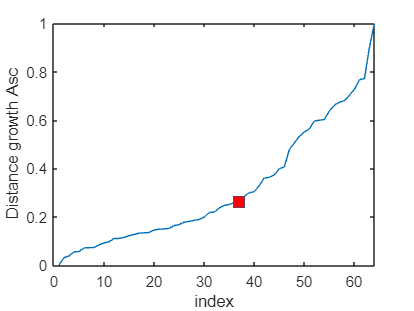

optrank_nongrowth = 1

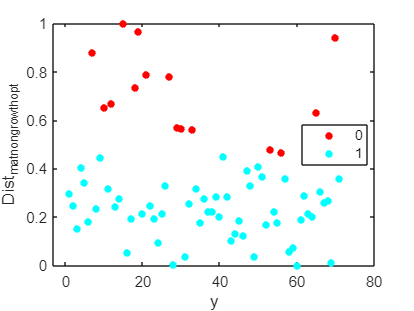

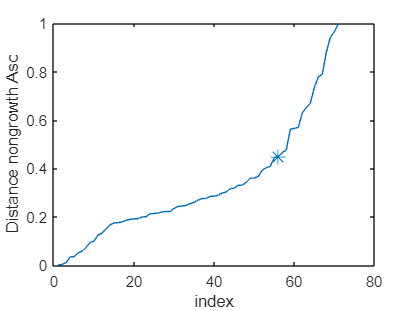

optrank_growth = 3

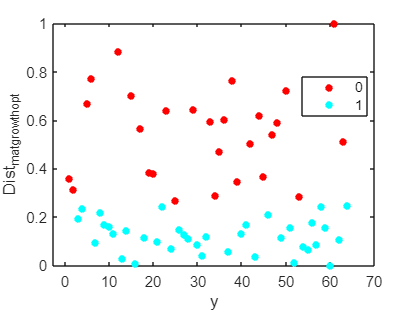

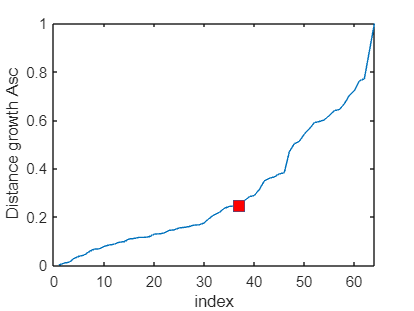

optrank_nongrowth = 2

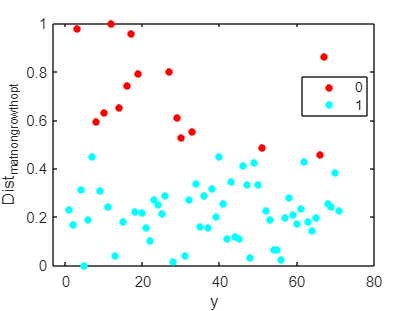

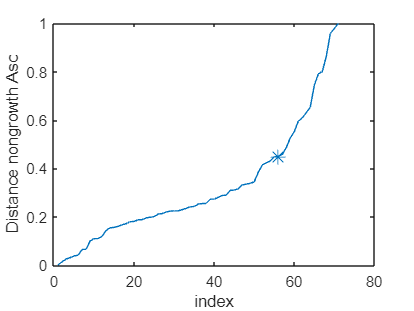

optrank_growth = 3

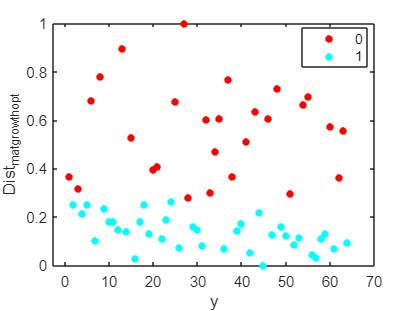

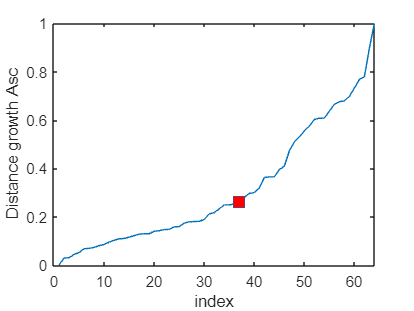

optrank_nongrowth = 2

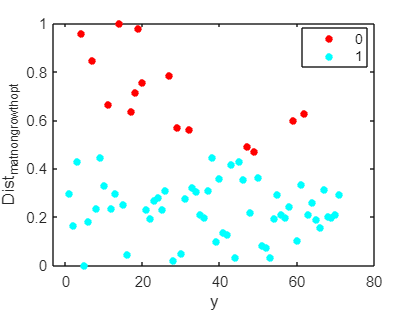

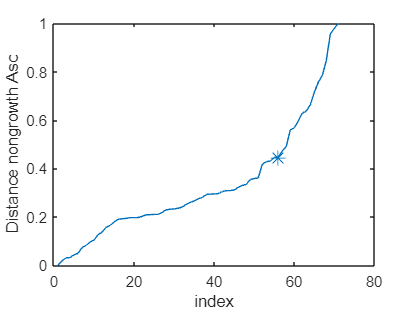

optrank_growth = 3

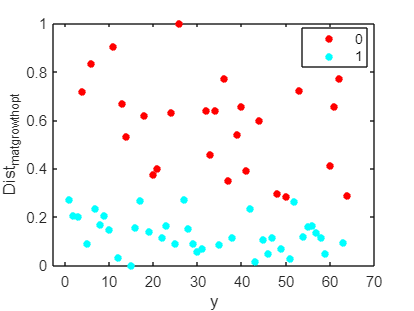

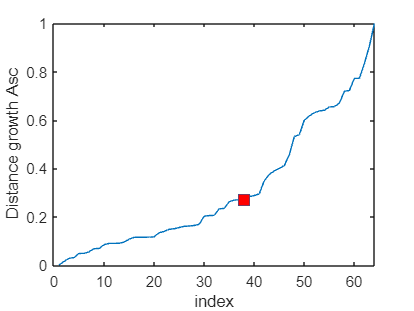

optrank_nongrowth = 2

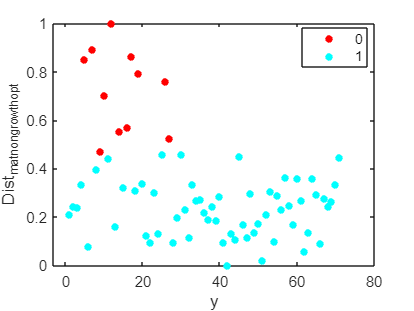

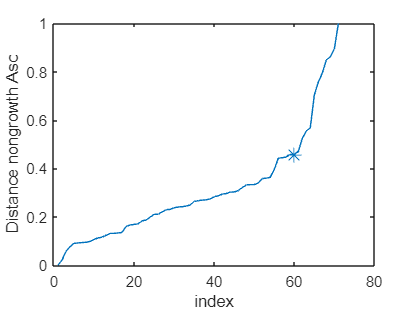

splitfolder = 'split7'

per =      0     5    10    15    20    25


optrank_growth = 2

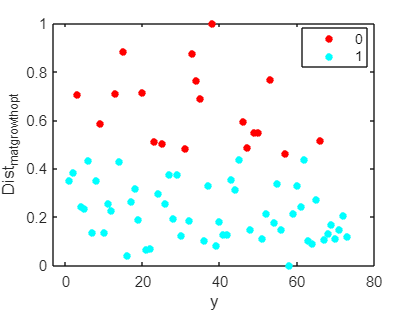

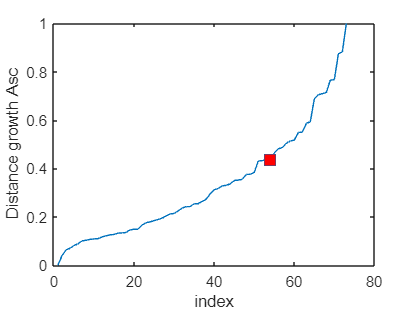

optrank_nongrowth = 2

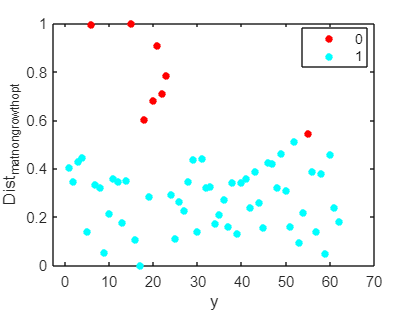

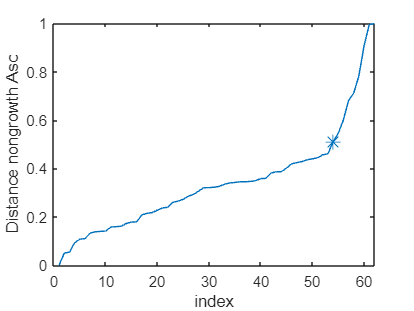

optrank_growth = 1

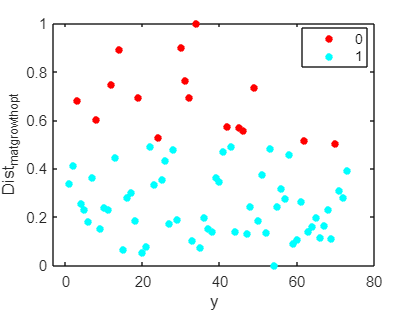

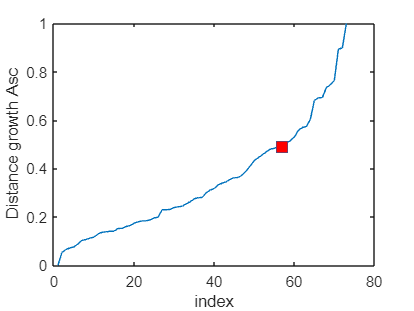

optrank_nongrowth = 1

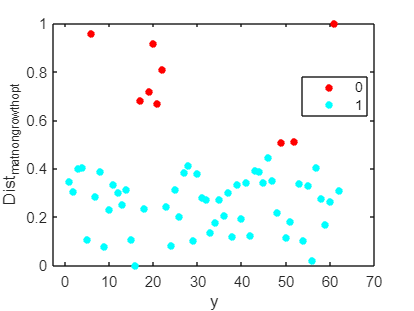

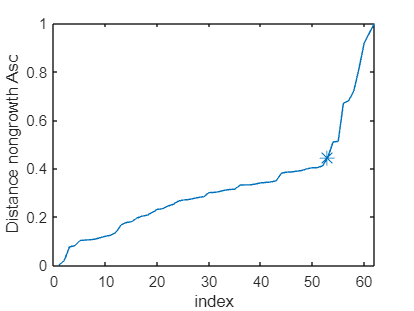

optrank_growth = 2

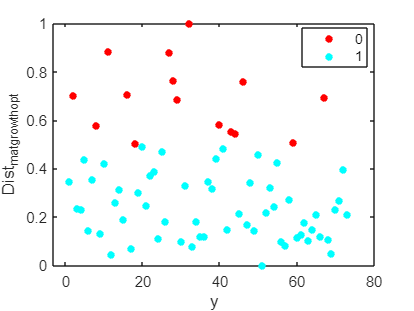

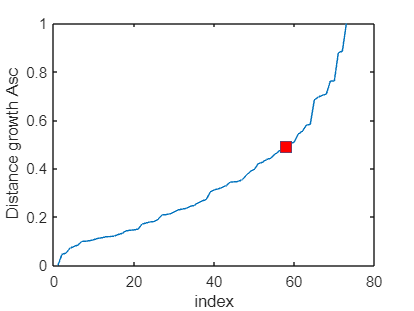

optrank_nongrowth = 1

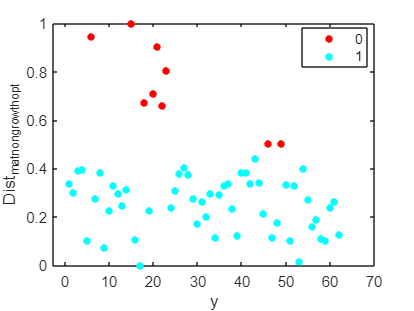

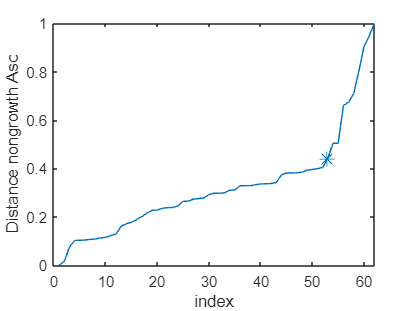

optrank_growth = 2

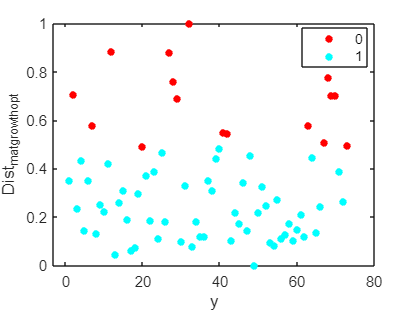

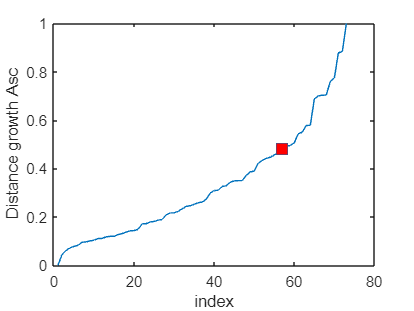

optrank_nongrowth = 1

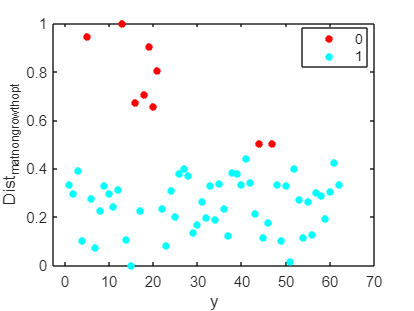

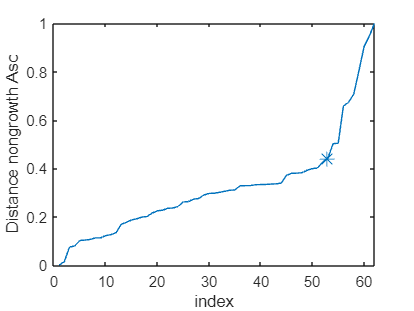

optrank_growth = 3

optrank_nongrowth = 1

optrank_growth = 1

optrank_nongrowth = 1

splitfolder = 'split8'

per =      0     5    10    15    20    25


optrank_growth = 3

optrank_nongrowth = 1

optrank_growth = 3

optrank_nongrowth = 1

optrank_growth = 3

optrank_nongrowth = 2

optrank_growth = 3

optrank_nongrowth = 1

optrank_growth = 3

optrank_nongrowth = 2

optrank_growth = 2

optrank_nongrowth = 1

splitfolder = 'split9'

per =      0     5    10    15    20    25


optrank_growth = 3

optrank_nongrowth = 1

optrank_growth = 3

optrank_nongrowth = 2

optrank_growth = 3

optrank_nongrowth = 2

optrank_growth = 3

optrank_nongrowth = 2

optrank_growth = 3

optrank_nongrowth = 3

optrank_growth = 3

optrank_nongrowth = 2

splitfolder = 'split10'

per =      0     5    10    15    20    25


optrank_growth = 1

optrank_nongrowth = 1

optrank_growth = 1

optrank_nongrowth = 2

optrank_growth = 1

optrank_nongrowth = 1

optrank_growth = 1

optrank_nongrowth = 1

optrank_growth = 2

optrank_nongrowth = 2

optrank_growth = 1

optrank_nongrowth = 2

figure
for j = [1,2,3,4,5,6,7,8,9,10]
     splitfolder=strcat('split',num2str(j))
    M=importdata("C:\Users\shukl\Documents\GitHub\plant_growth\split1\plant_train_set.csv",",",1);
    per =[0,5,10,15,20,25]%,10,5,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\plant_growth\
        % mkdir (splitfolder)
        cd (splitfolder)
        folder=strcat('per',num2str(percent));
        %         mkdir (folder)
        cd (folder)

        
        my_file = strcat('plant_misclass_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);
        %cd (folder)

        growth=File(File(:,7)==1,1:6);
        T_growth=growth.';



        nongrowth=File(File(:,7)==0,1:6);
        T_nongrowth=nongrowth.';


        folder_l1=strcat('ACE_opt_dist_optrank_angle_l1pca_per',num2str(percent));
        mkdir (folder_l1)

        ranks=[1,2,3];%,6,7,8];

        error_growth = nan(size(ranks));
        numgrowth=length(T_growth);
        Dist_mat_growth_array_asc=nan(length(ranks),numgrowth);
        threshold_rank_growth=nan(size(ranks));
        elbow_indx_rank_growth=nan(size(ranks));

        for i = ranks
            % fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\plant_growth\

            T_growth_temp=T_growth;
            Dist_mat_growth=[];


            BF_growth=l1pca_BF(T_growth,i,1,10,10,'');
            for k = 1 : numgrowth
                A=T_growth(:,k);
                Dist_mat_growth(k)=norm((A-(BF_growth*BF_growth.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_growth,[],"all");
            max_val=max(Dist_mat_growth,[],"all");
            Dist_mat_growth= Dist_mat_growth-min_val;%]/[max_val-min_val]
            Dist_mat_growth=Dist_mat_growth /(max_val-min_val);


            Dist_mat_growth_array_asc(i,:)=Dist_mat_growth;
            [Dist_mat_growth_asc,Indx_growth]=sort(Dist_mat_growth,"ascend");


            [elbow_growth_err_angle,elbow_indx_growth]=knee_pt_angle((Dist_mat_growth_asc));

            error_growth(i)=elbow_growth_err_angle;
            threshold_rank_growth(i)=Dist_mat_growth_asc(elbow_indx_growth);
            elbow_indx_rank_growth(i)=elbow_indx_growth;

        end

        [~,optrank_growth]= max(error_growth)

        Dist_mat_growth_opt=Dist_mat_growth_array_asc(optrank_growth,:);
        threshold_dist_growth= threshold_rank_growth(optrank_growth);
        elbow_indx_growth_opt=elbow_indx_rank_growth(optrank_growth);

        ind_O_growth=find(Dist_mat_growth_opt>threshold_dist_growth);
        ind_I_growth=find(Dist_mat_growth_opt<=threshold_dist_growth);


        cluster_growth=zeros(size(Dist_mat_growth_opt));
        cluster_growth(ind_I_growth)=1;
        figure
        % y= 1:1:length(growth);
        % numGroups = length(unique(cluster_growth));
        % gscatter(y,Dist_mat_growth_opt,cluster_growth,hsv(numGroups))
        % 
        % figure
        % plot(sort(Dist_mat_growth_opt,"ascend"),'-s',"MarkerIndices",(elbow_indx_growth_opt),'MarkerFaceColor','red','MarkerSize',10 )
        % xlabel("index")
        % ylabel("Distance growth Asc")
        % ind_O_growth;


        T_growth_temp(:,ind_O_growth)=[];
        length(T_growth_temp);


        Final_growth=T_growth_temp';
        c1=ones(size(Final_growth,1),1);
        Final_growth=[Final_growth c1];


        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        error_nongrowth = nan(size(ranks));
        numnongrowth=length(T_nongrowth);
        Dist_mat_nongrowth_array_asc=nan(length(ranks),numnongrowth);
        threshold_rank_nongrowth=nan(size(ranks));
        elbow_indx_rank_nongrowth=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\plant_growth\

            T_nongrowth_temp=T_nongrowth;
            Dist_mat_nongrowth=[];


            BF_nongrowth=l1pca_BF(T_nongrowth,i,1,20,20,'');
            for k = 1 : numnongrowth
                A=T_nongrowth(:,k);
                Dist_mat_nongrowth(k)=norm((A-(BF_nongrowth*BF_nongrowth.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_nongrowth,[],"all");
            max_val=max(Dist_mat_nongrowth,[],"all");
            Dist_mat_nongrowth= Dist_mat_nongrowth-min_val;%]/[max_val-min_val]
            Dist_mat_nongrowth=Dist_mat_nongrowth /(max_val-min_val);


            Dist_mat_nongrowth_array_asc(i,:)=Dist_mat_nongrowth;
            [Dist_mat_nongrowth_asc,Indx_nongrowth]=sort(Dist_mat_nongrowth,"ascend");


            [elbow_nongrowth_err_angle,elbow_indx_nongrowth]=knee_pt_angle(Dist_mat_nongrowth_asc);

            error_nongrowth(i)=elbow_nongrowth_err_angle;
            threshold_rank_nongrowth(i)=Dist_mat_nongrowth_asc(elbow_indx_nongrowth);
            elbow_indx_rank_nongrowth(i)=elbow_indx_nongrowth;

        end

        [~,optrank_nongrowth]= max(error_nongrowth)

        Dist_mat_nongrowth_opt=Dist_mat_nongrowth_array_asc(optrank_nongrowth,:);
        threshold_dist_nongrowth= threshold_rank_nongrowth(optrank_nongrowth);
        elbow_indx_nongrowth_opt=elbow_indx_rank_nongrowth(optrank_nongrowth);

        ind_O_nongrowth=find(Dist_mat_nongrowth_opt>threshold_dist_nongrowth);
        ind_I_nongrowth=find(Dist_mat_nongrowth_opt<=threshold_dist_nongrowth);


        cluster_nongrowth=zeros(size(Dist_mat_nongrowth_opt));
        cluster_nongrowth(ind_I_nongrowth)=1;
        figure
        % y= 1:1:length(nongrowth);
        % numGroups = length(unique(cluster_nongrowth));
        % gscatter(y,Dist_mat_nongrowth_opt,cluster_nongrowth,hsv(numGroups))
        % 
        % figure
        % plot(sort(Dist_mat_nongrowth_opt,"ascend"),'-*',"MarkerIndices",(elbow_indx_nongrowth_opt),'MarkerFaceColor','red','MarkerSize',10 )
        % xlabel("index")
        % ylabel("Distance nongrowth Asc")
        % ind_O_nongrowth;


        T_nongrowth_temp(:,ind_O_nongrowth)=[];
        length(T_nongrowth_temp);

        Final_nongrowth=T_nongrowth_temp';

        c2=0*ones(size(Final_nongrowth,1),1);
        Final_nongrowth=[Final_nongrowth c2];


        cd C:\Users\shukl\Documents\GitHub\plant_growth\
        cd (splitfolder)
        cd (folder)

        cd (folder_l1)

        L1pca_file=(horzcat(Final_growth.',Final_nongrowth.')).';

        L1pca_file = array2table(L1pca_file);
        L1pca_file.Properties.VariableNames(1:7)=  M.colheaders;
        filel1pca=strcat('plant_misclass_per',num2str(percent),'_ACE_l1pca.csv');
        writetable(L1pca_file,filel1pca);
    end
end